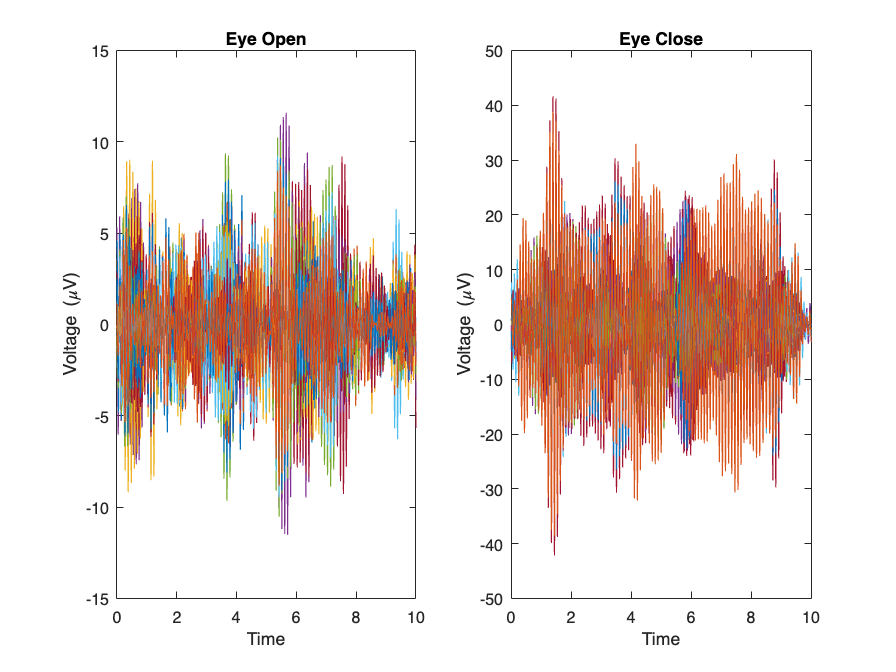

% Load variables
load('example_data/eeg_open.mat'); %load variable 'eeg_alpha_open'
load('example_data/eeg_close.mat'); %load variable 'eeg_alpha_close'

% Visulization of the EEG data
srate = 512;
times_label = 1/srate:1/srate:10;
figure(1)
clf
subplot(121)
plot(times_label.',eeg_alpha_open.')
xlim([0,10])
title('Eye Open')
ylabel('Voltage (\muV)')
xlabel('Time')
subplot(122)
plot(times_label.',eeg_alpha_close.')
xlim([0,10])
title('Eye Close')
ylabel('Voltage (\muV)')
xlabel('Time')

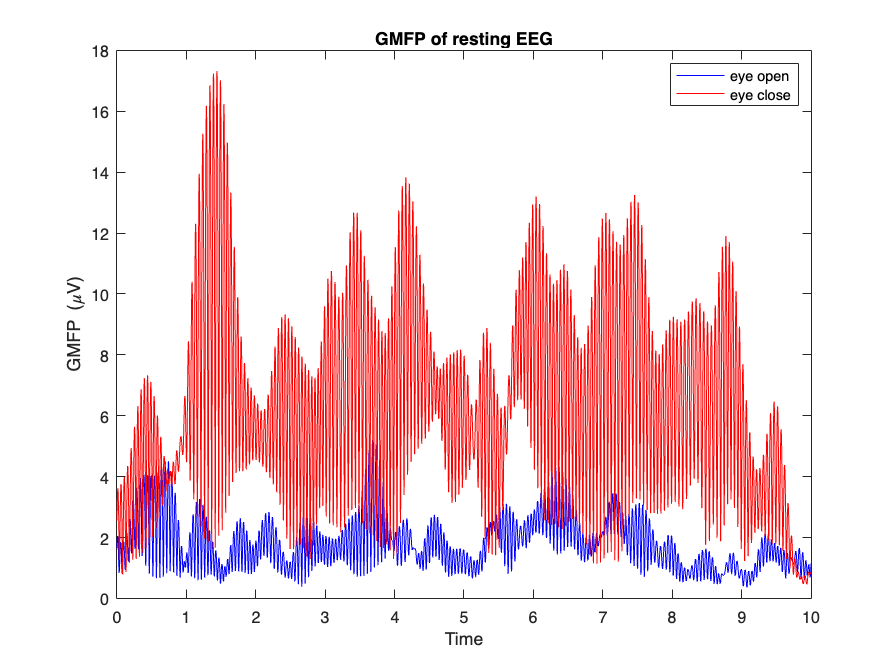

% Visulize GMFP results of two conditions
gmfp_open = gmfp(eeg_alpha_open);
gmfp_close = gmfp(eeg_alpha_close);
figure(2)
clf
plot(times_label,gmfp_open,'blue')
hold on
plot(times_label,gmfp_close,'red')
xlim([0,10])
title('GMFP of resting EEG')
ylabel('GMFP (\muV)')
xlabel('Time')
legend({'eye open','eye close'})

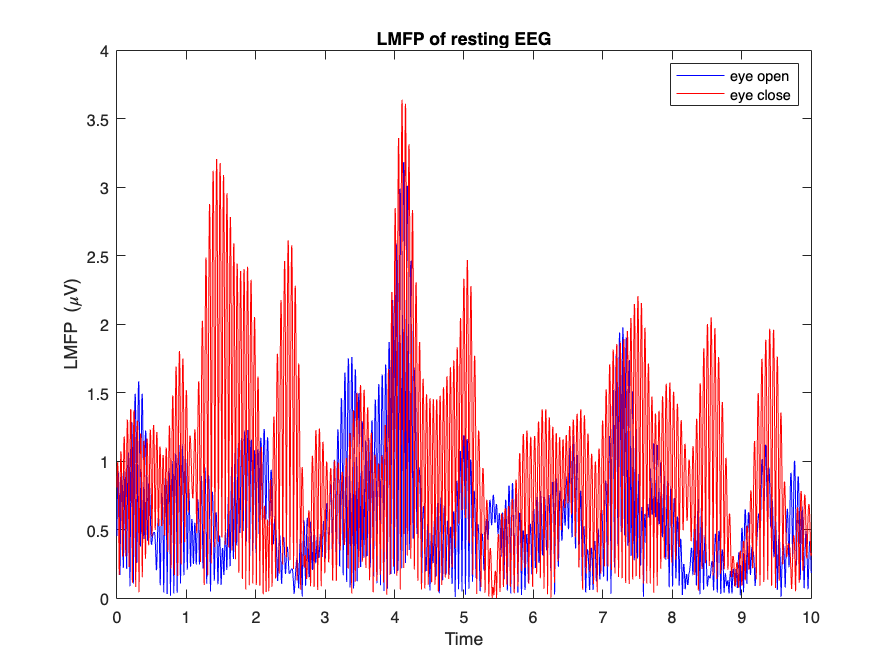

% Visulize LMFP results at prefrontal region (FP1, FP2, Fz) of two conditions
elec_num = [1,2,5]; %FP1(1), FP2(2), Fz(5)
lmfp_open = lmfp(eeg_alpha_open,elec_num);
lmfp_close = lmfp(eeg_alpha_close,elec_num);
figure(3)
clf
plot(times_label,lmfp_open,'blue')
hold on
plot(times_label,lmfp_close,'red')
xlim([0,10])
title('LMFP of resting EEG')
ylabel('LMFP (\muV)')
xlabel('Time')
legend({'eye open','eye close'})

Signifcant difference observed in GMFP, but no significant difference contributed from the prefrontal region (FP1, FP2, Fz). 